# EPFL ENV-424 - Water Ressource Engineering Project - Autumn 2022 - Group D

# Plan of a multipurpose reservoir

A reservoir is used for hydroelectrical energy production and flood prevention. You should evaluate the feasibility of improving the flood control operations of an existing reservoir of a hydropower plant. A larger fraction of the storage needs to be reserved for flood control and cannot be used for hydroelectric generation. The downstream part of the river should be protected from floods larger than Q lim . The larger the volume for hydroelectric use, the higher the energy production. The larger the volume for flood control, the more efficiently floods can be attenuated. The two uses (hydroelectric and flood control) are therefore in competition. The goal of the assignment is to estimate the trade off between money earned with energy production and probability that the released flow Q out exceeds Q lim , as a function of the volume reserved for flood control. Note that the discharge used for hydropower generation is then released into a different river system.

`All deliverables can be easily found as they are introduced in this specific font.`

## **Read all input parameters (P, Q, etc.) **

load data/P.txt
load data/Q_obs.txt
load data/temperature.txt
load data/kc.txt
load data/area_rating_curve.txt %[elevation above sea level, lake area]

## **Setting the parameters **

%hydrological model
sw=0.25;     %wilting point
s1=0.4;      %soil moisture stress threshold
n=0.3;       %porosity
Qb=7;        %m^3/s, baseflow
tsup=22;     %h, mean superficial residence time
A=4000;      %km^2, catchment area
phi=38;      %degree, latitude% 
n_years=6;  

%ARBITRARY VALUES
Ksat=3*10^-6;         %saturated hydraulic conductivity, K(s)=Ksat*s^c [m/s]
c=5;          
tsub=8*24;        %h, mean sub-superficial residence time
z=2;          %m, root zone thickness

dt=1;
doTest=1;

## **Calibration of the hydrological model**

%[Ksat, c, tsub, z, NS] = GroupD_f_calibration(Q_obs, phi, temperature, n_years, P, sw, s1, kc, n, Qb, tsup, A, dt, tsub, c, Ksat, z, doTest)

`1. Best parameters for the hydrological model: `

Ksat = 9.629e-07

Ksat = 9.6290e-07

c = 7.5651

c = 7.5651

z = 559.5589

z = 559.5589

tsub = 68.2382

tsub = 68.2382

NS = 0.8773

NS = 0.8773

## **Run the hydrological model **

[Q, R, I, s, L, ET] = GroupD_f_hydromodel(phi,temperature,n_years,P,Ksat,sw,s1,kc,n,Qb,tsup,tsub,A,c,dt,z,doTest);

`2. Plot the time series (6-year-long) of precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the given precipitation).`

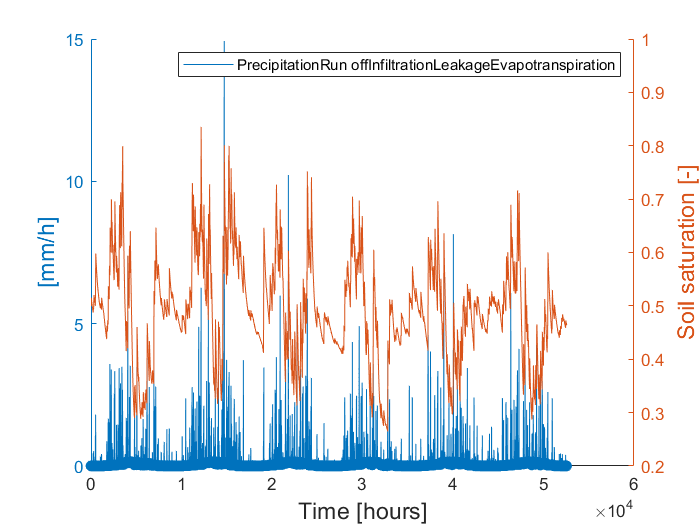

figure  
yyaxis left 
plot(P);
hold on 
plot(R);   
plot(I);
plot(L);
plot(ET);
ylabel('[mm/h]','fontsize',14) 

yyaxis right 
plot(s);
ylabel('Soil saturation [-]','fontsize',14) 

legend(['Precipitation', 'Run off', 'Infiltration', 'Leakage', 'Evapotranspiration'])
xlabel('Time [hours]','fontsize',14)
box off

## **Discharge generation **

Nyears_gen = 100;               %[years]
max_Kc = Ksat(NS==max(NS));     %[m/s]  hydraulic conductivity (saturated soil) for the maximum Nash-Sutcliffe index NS
max_z = z(NS==max(NS));         %[mm]   root zone depth for the maximum Nash-Sutcliffe index NS
max_c = c(NS==max(NS));         %[-]    exponent for power-law relation for the maximum Nash-Sutcliffe index NS
max_tsub = tsub(NS==max(NS));   %[h]    mean sub-superficial residence time for the maximum Nash-Sutcliffe index NS

[time_gen,Q_gen,R_gen,I_gen,soil_saturation_gen,L_gen,ET_gen,P_gen_mean_monthly] = GroupD_f_discharge(Nyears_gen, P, temperature, kc, dt, n, max_z,max_Kc,sw,s1,max_c,tsup,max_tsub,A,Qb,phi,doTest);

`3. Plot the time series of observed discharge and of the discharge as simulated by the hydrological model with the best fit parameters`

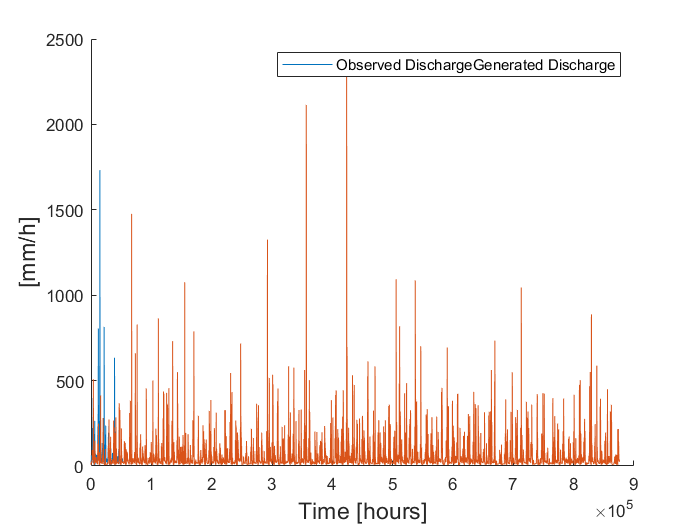

figure  
plot(Q_obs);
hold on 
plot(Q_gen);   
legend(['Observed Discharge', 'Generated Discharge'])
ylabel('[mm/h]','fontsize',14) 
xlabel('Time [hours]','fontsize',14)
box off

`4. Plot Markov chains of the calibrated parameters and sequences of values of N S and T SA as a function of the number of iterations. Only plot accepted parameter sets.`

`5. Plot the comparison between the statistics (mean, standard deviation, α and λ) of the observed and generated precipitation.`

`6. Plot the time series (100-year-long) of generated precipitation in [mm/h], run off in [mm/h], infiltration in [mm/h], soil moisture, leakage in [mm/h] and evapotranspiration in [mm/h] for the calibrated hydrological model forced by the generated precipitation).`

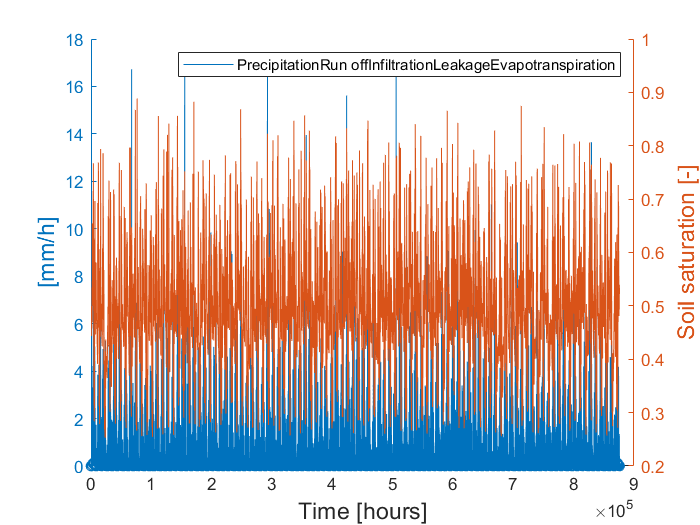

figure 
yyaxis left
plot(P_gen_mean_monthly);
hold on 
plot(R_gen);   
plot(I_gen);
plot(L_gen);
plot(ET_gen);
ylabel('[mm/h]','fontsize',14) 

yyaxis right 
plot(soil_saturation_gen);
ylabel('Soil saturation [-]','fontsize',14) 

legend(['Precipitation', 'Run off', 'Infiltration', 'Leakage', 'Evapotranspiration'])
xlabel('Time [hours]','fontsize',14)
box off

`7. Plot the area and the volume rating curves for the given levels.`

`8. Report the minimum flow (discharge that is equalled or exceeded 95% of the time) of the generated discharge and plot the discharge duration curves.`

% TO CHANGE 
Q347 = 30 % [m3/s]

Q347 = 30

## **Hydropower production, Reservoir routing and Flood control **

`First:`` compute the volume rating curve of the reservoir and the minimum flow that is released at all times`

`final goal:`` estimate the power production and the flooding probability as a function of the volume (i.e. of the maximum level for hydroelectric use) reserved for flood control.`

% A 
% ligne 162, V(t-1) = 
% hT ? 
% plots

% KNOWN PARAMETERS 
% Of the reservoir 
Cqg = 0.6; % [-] Discharge coefficient for sluice gate 
Cqs = 0.7; % [-] Discharge coefficient for spillway 
Lspill = 140; % [m] Length of the spillway 
p = 19; % [m] level of the spillway crest 
% Of the river 
Qlim = 100; % [m3/s] discharge limit fro floods 
% Of the power plant 
eta = 0.73; % [-] Turbine efficiency 
QT = 35; % [m3/s] discharge to the turbine 
delta_h = 75; % [m] difference between the elevation of the empty pool and the tailrace level
lminHU = 7; % [m] min level for hydroelectric production 
D = 3.3; % [m] pipe diameter 
Lp = 1200; % [m] pipe length 
TotWH = 16; % [h] Total working hours 

gamma = 9800; % [N/m3] specific weight of water (approximation at Earth ambiant temperatures)
g = 9.81; % [m/s2] gravity on Earth
% h_min_P = 610 %[masl]
% h_min = 600 % [masl]
% h_max = 620 % [masl]
% h_spill = 618 % [masl]

% VARIABLE INITIALIZATION
nyears = 10; % [y] number of years 
ndays = 10*365; % [d] number of days
nt = ndays * 24; % [h] nb of total hours ie timesteps
Qout = zeros(nt, 19-9);
QHU = zeros(nt, 19-9);
V = zeros(nt, 19-9);
l = zeros(nt, 19-9);
P = zeros(nt, 19-9);
Qg = zeros(nt, 19-9);
flood_p = zeros(nt, 19-9);

% Assume a maximum level for HU (e.g. l max,HU = 15 m).
% Repeat for different values of the maximum level for HU (from 9 to 19 m, step equal or lower to 1 m)
for lmaxHU = 9:19 
    % Get the volume by multiplying the levele by the lake area at this level 
    VmaxHU = lmaxHU*area_rating_curve(lmaxHU+1, 2);
    for d=1:ndays
        for h = 1:24
            t = (d-1)*24 + h;
            % DETERMINATION OF WETHER THE TURBINES ARE WORKING OR NOT 
            % If at midnight the level in the reservoir is above the minimum level for hydroelectrical use, 
            % the plant will work during that day, otherwise it will not
            turb_day = l(d*24, lmaxHU) > lminHU;  
            % The turbines work between 06:00 and 22:00 
            turb = turb_day && 6<h && h<22; 
            if ~turb  % If turbines do not work, the values are ? 
                QHU(t, lmaxHU) = 0; 
            else 
                QHU(t, lmaxHU) = QT; 
            end

            % RESERVOIR ROUTING WITH FLOOD CONTROL 
            if t==1
                l(t, lmaxHU) = lmaxHU;
                V(t, lmaxHU) = VmaxHU;
                tmp = V(t, lmaxHU) + abs(Q(t) - QHU(t, lmaxHU)) - VmaxHU;
                Qg(t, lmaxHU) = max(Q347, min(Qlim, tmp));
                Qg(t, lmaxHU)
                Asg = y2/Cqg % Sluice gate opening area  
                if l(t, lmaxHU) <= p 
                Qout(t, lmaxHU) = Cqg*Asg*sqrt(2*g*l(t, lmaxHU));
                else 
                    Qout(t, lmaxHU) = Cqg*Asg*sqrt(2*g*l(t, lmaxHU)) + Cqs*L*sqrt(2*g*(l(t, lmaxHU)-p)^3);
                end 
                P(t, lmaxHU) = 0;
                
            else                     
                l(t, lmaxHU) = level_volume(area_rating_curve(:, 2).*area_rating_curve(:, 1),area_rating_curve(:, 2), V(t-1, lmaxHU));
                tmp = V(t-1, lmaxHU) + abs(Q(t) - QHU(t, lmaxHU)) - VmaxHU;
                Qg(t, lmaxHU) = max(Q347, min(Qlim, tmp));
                Asg = Qg(t, lmaxHU) % Sluice gate opening area  
                if l(t, lmaxHU) <= p 
                    Qout(t, lmaxHU) = Cqg*Asg*sqrt(2*g*l);
                else 
                    Qout(t, lmaxHU) = Cqg*Asg*sqrt(2*g*l) + Cqs*L*sqrt(2*g*(l-p)^3);
                end 
                dV = Q(t) - Qout(t, lmaxHU) - QHU(t, lmaxHU); 
                V(t, lmaxHU) = V(t-1, lmaxHU) + dV;
                
                % AVERAGE ANNUAL ENERGY PRODUCTION
                hT =  % [m] Net head 
                % To compute the net head of the turbine, account for frictional head losses along the pipe, entrance head loss (half of the kinematic term) and exit head loss (one kinematic term)  
                P(t, lmaxHU) = eta*gamma*QHU(t, lmaxHU)*hT;
             end
            
                   
            
            % PROBABILITY THAT QOUT EXCEEDS 100 M3/S. For numerical reasons, the conditions should read Qout > 101 m3/s.
            flood_p(t, lmaxHU) = Qout > 101;
        end 
    end 
end 

Unrecognized function or variable 'hT'.

`9. For a maximum level for hydroelectric use of 15 m, plot the time series (100 years long) of input discharge, output discharge, volume within the reservoir and level.`

plot(Q)
holf on 
plot(Qout(:, 15+1))
plot(V(:, 15+1))
plot(h(:, 15+1))

`10. Plot the average annual energy production in [GWh] and the probability that Q out exceeds Q lim for different values of the maximum level for hydroelectrical use.`

tiledlayout(4,2)
for i = 1:4
    nexttile([i, 2])
    plot(P(:, 9 + 2*i))
    nexttile
    plot(flood_p(:, 9 + 2*i))
end 

`11. Plot the Pareto front of average annual energy production in [GWh] vs the probability that Q out exceeds Q lim computed from different values of the maximum level for hydroelectrical use.`

plot(-P, flood_p)